import mlreportgen.dom.*
cd ('C:\Users\dml36958\Desktop\STFC_Gits\HEXITEC')
D = Document('CdTe_500V','docx','Template.dotx')

D =   Document with properties:

           OutputPath: 'C:\Users\dml36958\Desktop\STFC_Gits\HEXITEC\CdTe_500V'
          PackageType: 'zipped'
       ForceOverwrite: 1
         StreamOutput: 0
         TitleBarText: ''
          HTMLHeadExt: ''
         TemplatePath: 'Template.dotx'
                 Type: 'DOCX'
        CurrentHoleId: ''
      CurrentHoleType: ''
    CurrentPageLayout: []
           OpenStatus: 'unopened'
               Parent: []
             Children: [1×0 mlreportgen.dom.Node]
                  Tag: 'dom.Document:6'
                   Id: '6'


open(D)

ans = logical
   1



% Title Page Sequence
moveToNextHole(D)

ans = 'TileBox'

titleText = Text('CdTe Detectors', 'Title Style');
append(D, titleText)

ans =   Text with properties:

             Content: 'CdTe Detectors'
                Bold: []
              Italic: []
               Color: []
     BackgroundColor: []
           Underline: []
          WhiteSpace: []
      FontFamilyName: []
            FontSize: []
              Strike: []
           StyleName: 'Title Style'
               Style: {1×0 cell}
    CustomAttributes: []
              Parent: [1×1 mlreportgen.dom.Document]
            Children: [1×0 mlreportgen.dom.Node]
                 Tag: 'dom.Text:30'
                  Id: '30'



moveToNextHole(D)

ans = 'AuthorBox'

authorText = Text('Rhian Mair Wheater', 'Heading Style');
append(D, authorText)

ans =   Text with properties:

             Content: 'Rhian Mair Wheater'
                Bold: []
              Italic: []
               Color: []
     BackgroundColor: []
           Underline: []
          WhiteSpace: []
      FontFamilyName: []
            FontSize: []
              Strike: []
           StyleName: 'Heading Style'
               Style: {1×0 cell}
    CustomAttributes: []
              Parent: [1×1 mlreportgen.dom.Document]
            Children: [1×0 mlreportgen.dom.Node]
                 Tag: 'dom.Text:35'
                  Id: '35'



moveToNextHole(D)

ans = 'DateBox'

today = date;
dateText = Text(today, 'Heading Style')

dateText =   Text with properties:

             Content: '30-Nov-2020'
                Bold: []
              Italic: []
               Color: []
     BackgroundColor: []
           Underline: []
          WhiteSpace: []
      FontFamilyName: []
            FontSize: []
              Strike: []
           StyleName: 'Heading Style'
               Style: {1×0 cell}
    CustomAttributes: []
              Parent: []
            Children: [1×0 mlreportgen.dom.Node]
                 Tag: 'dom.Text:40'
                  Id: '40'


append(D, dateText)

ans =   Text with properties:

             Content: '30-Nov-2020'
                Bold: []
              Italic: []
               Color: []
     BackgroundColor: []
           Underline: []
          WhiteSpace: []
      FontFamilyName: []
            FontSize: []
              Strike: []
           StyleName: 'Heading Style'
               Style: {1×0 cell}
    CustomAttributes: []
              Parent: [1×1 mlreportgen.dom.Document]
            Children: [1×0 mlreportgen.dom.Node]
                 Tag: 'dom.Text:40'
                  Id: '40'



% Testing Conditions Sequence
biasV = -500; % in V
temp = 28; % in degrees C
xraySource = 'Am-241';
duration = 10; % in minutes

biasVoltageStr = strcat('Applied bias voltage of', num2str(biasV));
tempStr = strcat('Detector temperature maintained at', num2str(temp), char(176),'C');
durationStr = strcat('Exposure to an',xraySource,'source for a duration of', num2str(duration),'minutes');
conditionsList = UnorderedList({biasVoltageStr; tempStr; durationStr})

conditionsList =   UnorderedList with properties:

           StyleName: []
               Style: {1×0 cell}
    CustomAttributes: []
              Parent: []
            Children: [1×3 mlreportgen.dom.ListItem]
                 Tag: 'dom.UnorderedList:42'
                  Id: '42'


conditionsList.StyleName = 'Bulk Style'

conditionsList =   UnorderedList with properties:

           StyleName: 'Bulk Style'
               Style: {1×0 cell}
    CustomAttributes: []
              Parent: []
            Children: [1×3 mlreportgen.dom.ListItem]
                 Tag: 'dom.UnorderedList:42'
                  Id: '42'


moveToNextHole(D)

ans = 'TestConditons'

append(D, conditionsList)

ans =   UnorderedList with properties:

           StyleName: 'Bulk Style'
               Style: {1×0 cell}
    CustomAttributes: []
              Parent: [1×1 mlreportgen.dom.Document]
            Children: [1×3 mlreportgen.dom.ListItem]
                 Tag: 'dom.UnorderedList:42'
                  Id: '42'



% Importing Figures Sequence
analysedFilesLocation = 'J:\NewCdTe'

analysedFilesLocation = 'J:\NewCdTe'

cd (analysedFilesLocation)
analysedFiles = dir('1606*');
moveToNextHole(D)

ans = 'Detector Analysis'

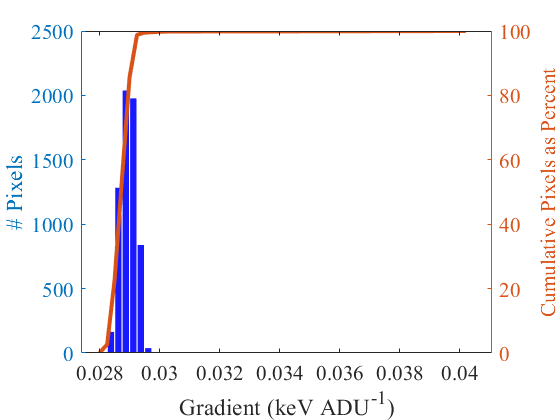

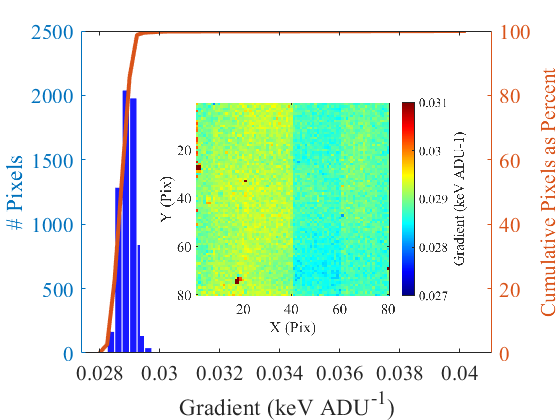

oldXLim =    -4.5650    3.4650


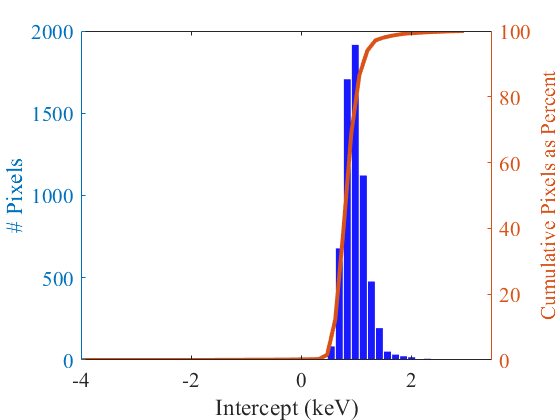

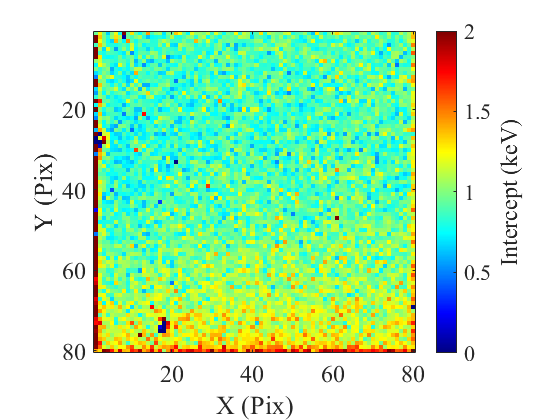

oldXLim =    -4.5650    3.4650


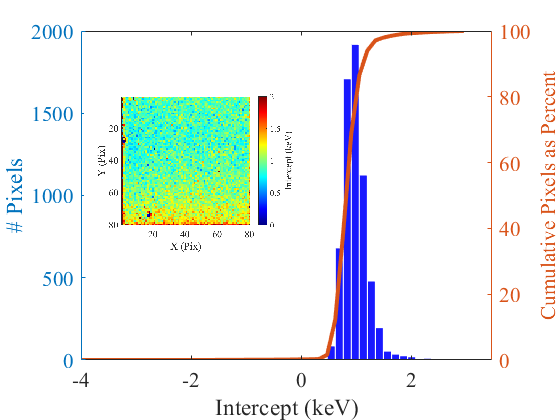

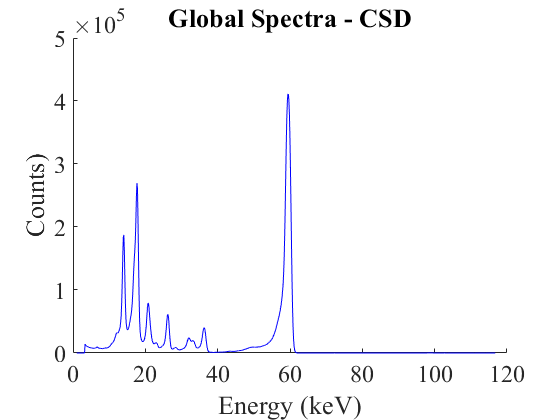

fig =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 101
        Name: ''
       Color: [1 1 1]
    Position: [100 100 1000 400]
       Units: 'pixels'

  Show all properties


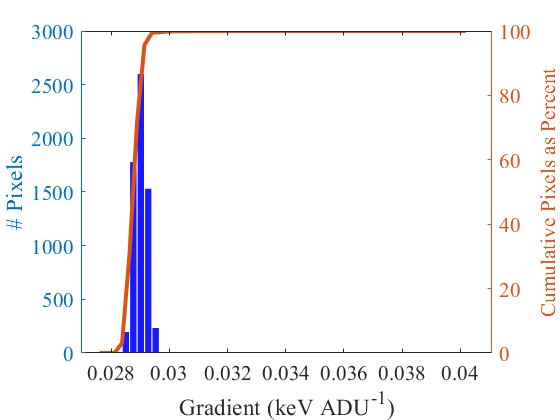

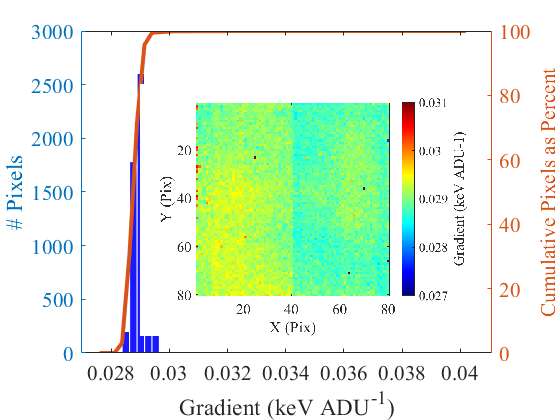

oldXLim =    -1.5675    4.3175


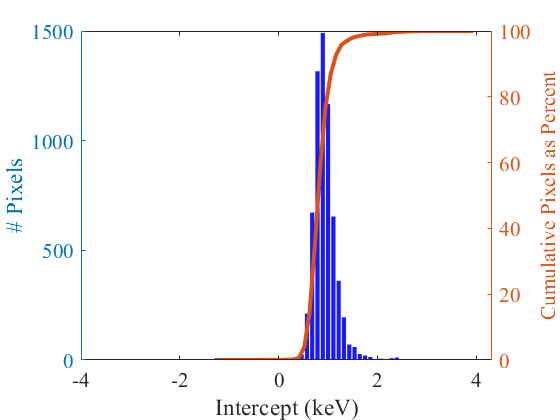

oldXLim =    -1.5675    4.3175


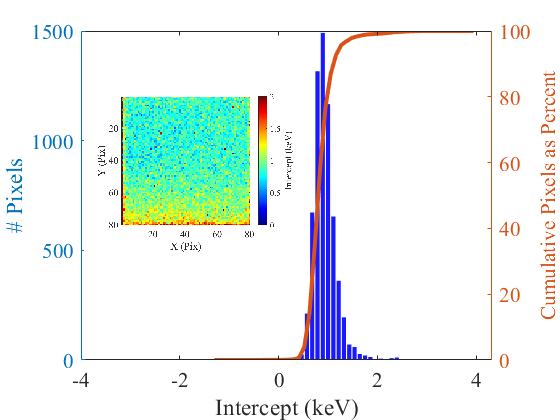

fig =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 101
        Name: ''
       Color: [1 1 1]
    Position: [100 100 1000 400]
       Units: 'pixels'

  Show all properties


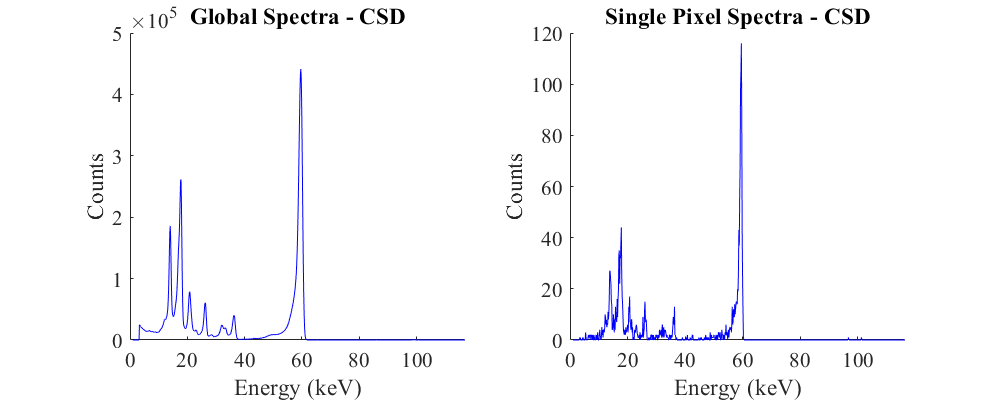

for ii =1:length(analysedFiles)    
    cd (strcat(analysedFilesLocation,'\',analysedFiles(ii).name));
    figuresLocation = dir('Figures_500V*');
    cd (figuresLocation.name);
    
    resultsDirectory = strcat(analysedFilesLocation,'\',analysedFiles(ii).name,'\',figuresLocation.name,'\');
    detectorID = Text(analysedFiles(ii).name, 'Detector Heading Style');
    append (D, detectorID);
    
    fig = open(strcat(resultsDirectory,'Image60keV.fig'));
    saveas(fig, strcat(resultsDirectory,'figure1.png'));
    docuFig = Image(strcat(resultsDirectory,'figure1.png'));
    docuFig.Style = {Height('4in')};
    append(D, docuFig);

    fig = open(strcat(resultsDirectory,'peakCents_60keV.fig'));
    saveas(fig, strcat(resultsDirectory,'figure2.png'));
    docuFig = Image(strcat(resultsDirectory,'figure2.png'));
    docuFig.Style = {Height('4in')};
    append(D, docuFig);

    fig = open(strcat(resultsDirectory,'GradientHistogram.fig'));
    saveas(fig, strcat(resultsDirectory,'figure3.png'));
%     docuFig = Image(strcat(resultsDirectory,'figure3.png'));  
%     docuFig.Style = {Height('4in')};
%     append(D, docuFig);
    
   
    fig = open(strcat(resultsDirectory,'Gradients.fig'));
    saveas(fig, strcat(resultsDirectory,'figure4.png'));
%     docuFig = Image(strcat(resultsDirectory,'figure4.png'));  
%     docuFig.Style = {Height('4in')};
%     append(D, docuFig);   
    
    fig = open(strcat(resultsDirectory,'GradientHistogram.fig'));
    axes('pos',[.25 .2 .6 .6])
    imshow(strcat(resultsDirectory,'figure4.png'))
    saveas(fig, strcat(resultsDirectory,'figureGradients.png'));
    docuFig = Image(strcat(resultsDirectory,'figureGradients.png'));  
    docuFig.Style = {Height('4in')};
    append(D, docuFig); 
    
    fig = open(strcat(resultsDirectory,'InterceptsHistogram.fig'));    
    oldXLim = xlim()
    xlim([-4 oldXLim(2)])
    saveas(fig, strcat(resultsDirectory,'figure5.png'));
    
    
    fig = open(strcat(resultsDirectory,'Intercepts.fig'));
    saveas(fig, strcat(resultsDirectory,'figure6.png'));
%     docuFig = Image(strcat(resultsDirectory,'figure6.png'));  
%     docuFig.Style = {Height('4in')};
%     append(D, docuFig);  
    
    fig = open(strcat(resultsDirectory,'InterceptsHistogram.fig'));
    oldXLim = xlim()
    xlim([-4 oldXLim(2)])
    axes('pos',[.15 .4 .4 .4])
    imshow(strcat(resultsDirectory,'figure6.png'))
    saveas(fig, strcat(resultsDirectory,'figureIntercepts.png'));
    docuFig = Image(strcat(resultsDirectory,'figureIntercepts.png'));  
    docuFig.Style = {Height('4in')};
    append(D, docuFig);  
    
    figure(101)    
    ax1 = subplot(1,2,1);
    set(gca,'FontSize',16,'fontname','times') 
    title('Global Spectra - CSD')
    ylabel('Counts')
    xlabel('Energy (keV)')
    
    ax2 = subplot(1,2,2);
    set(gca,'FontSize',16,'fontname','times') 
    title('Single Pixel Spectra - CSD')
    ylabel('Counts')
    xlabel('Energy (keV)')
    
    fig = open(strcat(resultsDirectory,'CalibratedGlobalCSDplot.fig'));
    axHand = gca;
    saveas(fig, strcat(resultsDirectory,'figure7.png'));
%     docuFig = Image(strcat(resultsDirectory,'figure7.png'));  
%     docuFig.Style = {Height('4in')};
%     append(D, docuFig);  
    
    fig1 = get(axHand,'children');
    copyobj(fig1,ax1);
    
    fig = open(strcat(resultsDirectory,'CalibratedCSDplotPixel4040.fig'));
    axHand = gca;
    saveas(fig, strcat(resultsDirectory,'figure8.png'));
    
    fig1 = get(axHand,'children');
    copyobj(fig1,ax2);
    
    fig = figure(101)
    set(gcf, 'Position',  [100, 100, 1000, 400])
    
%     docuFig = Image(strcat(resultsDirectory,'figure6.png'));  
%     docuFig.Style = {Height('4in')};
%     append(D, docuFig);  
    
    saveas(fig, strcat(resultsDirectory,'GlobalAndSingleSpec.png'))
    
    docuFig = Image(strcat(resultsDirectory,'GlobalAndSingleSpec.png'));  
    docuFig.Style = {Width('7in')};
    append(D, docuFig);  
    
%     fig1 = open(strcat(resultsDirectory,'GradientHistogram.fig'));
%     fig2 = open(strcat(resultsDirectory,'Gradients.fig'));    
%     saveas(fig1, strcat(resultsDirectory,'figure3.png'));
%     saveas(fig2, strcat(resultsDirectory,'figure4.png'));
%     
%     fig1Im = Image(strcat(resultsDirectory,'figure3.png'));
%     fig2Im = Image(strcat(resultsDirectory,'figure4.png'));
%     fig1Im.Style = {Height('3in')};
%     fig2Im.Style = {Height('2.5in')};
% 
%     lo_table=Table({fig1Im, fig2Im});
%     append(D, lo_table)
    append(D, PageBreak);
 end


cd ('C:\Users\dml36958\Desktop\STFC_Gits\HEXITEC')
close(D)

ans = logical
   1
